clc; clear;

%% Datos de la trayectoria
Pi = [0.13, -0.14171, 0.15362];
Pf = [-0.14279, -0.08409, 0.10116];

t_total = 30;
n  = 300;
dt = t_total/n;

d_total = Pf - Pi;
dist    = norm(d_total)

dist = 0.2837

u       = d_total / dist;
v_mag   = dist/t_total;     % llega a Pf justo en t_total
v_e     = (u * v_mag)';         % velocidad cartesiana deseada 3x1 [m/s]

%% Condición inicial por cinemática inversa
[th1_0, ~, th2_0, ~, d3_0] = cinematica_inversa(Pi(1), Pi(2), Pi(3));
q = [th1_0; th2_0; d3_0];

Q_hist = zeros(3, n+1);
P_hist = zeros(3, n+1);
Q_hist(:,1) = q;

%% Integración con Jacobiano inverso: q_dot = inv(Jv) * v_e
for i = 1:n
    [~, Px, Py, Pz, J] = cinematica(q(1), q(2), q(3));
    P_hist(:,i) = [Px; Py; Pz];

    Jv = J(1:3, :);                  % Jacobiano lineal 3x3 (cuadrado)
    if abs(det(Jv)) < 1e-8
        error('Singularidad en la iteración %d', i);
    end
    q_dot = inv(Jv) * v_e

    q = q + q_dot*dt;                % Euler hacia adelante
    Q_hist(:, i+1) = q;
end

q_dot =     0.0148
   -0.0789
    0.0017


q_dot =     0.0143
   -0.0785
    0.0017


q_dot =     0.0139
   -0.0780
    0.0017


q_dot =     0.0134
   -0.0776
    0.0017


q_dot =     0.0130
   -0.0771
    0.0017


q_dot =     0.0125
   -0.0767
    0.0017


q_dot =     0.0121
   -0.0762
    0.0017


q_dot =     0.0116
   -0.0758
    0.0017


q_dot =     0.0112
   -0.0753
    0.0017


q_dot =     0.0107
   -0.0749
    0.0017


q_dot =     0.0103
   -0.0745
    0.0017


q_dot =     0.0098
   -0.0740
    0.0017


q_dot =     0.0094
   -0.0736
    0.0017


q_dot =     0.0089
   -0.0732
    0.0017


q_dot =     0.0085
   -0.0728
    0.0017


q_dot =     0.0080
   -0.0724
    0.0017


q_dot =     0.0076
   -0.0720
    0.0017


q_dot =     0.0071
   -0.0716
    0.0017


q_dot =     0.0067
   -0.0711
    0.0017


q_dot =     0.0062
   -0.0707
    0.0017


q_dot =     0.0058
   -0.0703
    0.0017


q_dot =     0.0053
   -0.0699
    0.0017


q_dot =     0.0048
   -0.0695
    0.0017


q_dot =     0.0044
   -0.0692
    0.0017


q_dot =     0.0039
   -0.0688
    0.0017


q_dot =     0.0034
   -0.0684
    0.0017


q_dot =     0.0030
   -0.0680
    0.0017


q_dot =     0.0025
   -0.0676
    0.0017


q_dot =     0.0020
   -0.0672
    0.0017


q_dot =     0.0016
   -0.0668
    0.0017


q_dot =     0.0011
   -0.0664
    0.0017


q_dot =     0.0006
   -0.0661
    0.0017


q_dot =     0.0001
   -0.0657
    0.0017


q_dot =    -0.0004
   -0.0653
    0.0017


q_dot =    -0.0008
   -0.0649
    0.0017


q_dot =    -0.0013
   -0.0645
    0.0017


q_dot =    -0.0018
   -0.0642
    0.0017


q_dot =    -0.0023
   -0.0638
    0.0017


q_dot =    -0.0028
   -0.0634
    0.0017


q_dot =    -0.0033
   -0.0630
    0.0017


q_dot =    -0.0038
   -0.0627
    0.0017


q_dot =    -0.0043
   -0.0623
    0.0017


q_dot =    -0.0048
   -0.0619
    0.0017


q_dot =    -0.0053
   -0.0616
    0.0017


q_dot =    -0.0058
   -0.0612
    0.0017


q_dot =    -0.0063
   -0.0608
    0.0017


q_dot =    -0.0069
   -0.0604
    0.0017


q_dot =    -0.0074
   -0.0601
    0.0017


q_dot =    -0.0079
   -0.0597
    0.0017


q_dot =    -0.0084
   -0.0593
    0.0017


q_dot = 3×1
   -0.0089
   -0.0589
    0.0017


q_dot = 3×1
   -0.0095
   -0.0586
    0.0017


q_dot = 3×1
   -0.0100
   -0.0582
    0.0017


q_dot = 3×1
   -0.0106
   -0.0578
    0.0017


q_dot = 3×1
   -0.0111
   -0.0574
    0.0017


q_dot = 3×1
   -0.0116
   -0.0571
    0.0017


q_dot = 3×1
   -0.0122
   -0.0567
    0.0017


q_dot = 3×1
   -0.0127
   -0.0563
    0.0017


q_dot = 3×1
   -0.0133
   -0.0559
    0.0017


q_dot = 3×1
   -0.0139
   -0.0556
    0.0017


q_dot = 3×1
   -0.0144
   -0.0552
    0.0017


q_dot = 3×1
   -0.0150
   -0.0548
    0.0017


q_dot = 3×1
   -0.0156
   -0.0544
    0.0017


q_dot = 3×1
   -0.0161
   -0.0540
    0.0017


q_dot = 3×1
   -0.0167
   -0.0537
    0.0017


q_dot = 3×1
   -0.0173
   -0.0533
    0.0017


q_dot = 3×1
   -0.0179
   -0.0529
    0.0017


q_dot = 3×1
   -0.0185
   -0.0525
    0.0017


q_dot = 3×1
   -0.0190
   -0.0521
    0.0017


q_dot = 3×1
   -0.0196
   -0.0517
    0.0017


q_dot = 3×1
   -0.0202
   -0.0513
    0.0017


q_dot = 3×1
   -0.0208
   -0.0509
    0.0017


q_dot = 3×1
   -0.0215
   -0.0505
    0.0017


q_dot = 3×1
   -0.0221
   -0.0502
    0.0017


q_dot = 3×1
   -0.0227
   -0.0498
    0.0017


q_dot = 3×1
   -0.0233
   -0.0494
    0.0017


q_dot = 3×1
   -0.0239
   -0.0490
    0.0017


q_dot = 3×1
   -0.0245
   -0.0485
    0.0017


q_dot = 3×1
   -0.0252
   -0.0481
    0.0017


q_dot = 3×1
   -0.0258
   -0.0477
    0.0017


q_dot = 3×1
   -0.0264
   -0.0473
    0.0017


q_dot = 3×1
   -0.0271
   -0.0469
    0.0017


q_dot = 3×1
   -0.0277
   -0.0465
    0.0017


q_dot = 3×1
   -0.0284
   -0.0461
    0.0017


q_dot = 3×1
   -0.0290
   -0.0457
    0.0017


q_dot = 3×1
   -0.0297
   -0.0452
    0.0017


q_dot = 3×1
   -0.0303
   -0.0448
    0.0017


q_dot = 3×1
   -0.0310
   -0.0444
    0.0017


q_dot = 3×1
   -0.0317
   -0.0440
    0.0017


q_dot = 3×1
   -0.0323
   -0.0435
    0.0017


q_dot = 3×1
   -0.0330
   -0.0431
    0.0017


q_dot = 3×1
   -0.0337
   -0.0427
    0.0017


q_dot = 3×1
   -0.0344
   -0.0422
    0.0017


q_dot = 3×1
   -0.0350
   -0.0418
    0.0017


q_dot = 3×1
   -0.0357
   -0.0413
    0.0017


q_dot = 3×1
   -0.0364
   -0.0409
    0.0017


q_dot = 3×1
   -0.0371
   -0.0404
    0.0017


q_dot = 3×1
   -0.0378
   -0.0400
    0.0017


q_dot = 3×1
   -0.0385
   -0.0395
    0.0017


q_dot = 3×1
   -0.0392
   -0.0391
    0.0017


q_dot = 3×1
   -0.0399
   -0.0386
    0.0017


q_dot = 3×1
   -0.0406
   -0.0381
    0.0017


q_dot = 3×1
   -0.0413
   -0.0377
    0.0017


q_dot = 3×1
   -0.0420
   -0.0372
    0.0017


q_dot = 3×1
   -0.0427
   -0.0367
    0.0017


q_dot = 3×1
   -0.0434
   -0.0363
    0.0017


q_dot = 3×1
   -0.0441
   -0.0358
    0.0017


q_dot = 3×1
   -0.0448
   -0.0353
    0.0017


q_dot = 3×1
   -0.0456
   -0.0348
    0.0017


q_dot = 3×1
   -0.0463
   -0.0343
    0.0017


q_dot = 3×1
   -0.0470
   -0.0338
    0.0017


q_dot = 3×1
   -0.0477
   -0.0333
    0.0017


q_dot = 3×1
   -0.0484
   -0.0328
    0.0017


q_dot = 3×1
   -0.0492
   -0.0323
    0.0017


q_dot = 3×1
   -0.0499
   -0.0318
    0.0017


q_dot = 3×1
   -0.0506
   -0.0313
    0.0017


q_dot = 3×1
   -0.0513
   -0.0308
    0.0017


q_dot = 3×1
   -0.0520
   -0.0303
    0.0017


q_dot = 3×1
   -0.0528
   -0.0298
    0.0017


q_dot = 3×1
   -0.0535
   -0.0292
    0.0017


q_dot = 3×1
   -0.0542
   -0.0287
    0.0017


q_dot = 3×1
   -0.0549
   -0.0282
    0.0017


q_dot = 3×1
   -0.0556
   -0.0276
    0.0017


q_dot = 3×1
   -0.0564
   -0.0271
    0.0017


q_dot = 3×1
   -0.0571
   -0.0266
    0.0017


q_dot = 3×1
   -0.0578
   -0.0260
    0.0017


q_dot = 3×1
   -0.0585
   -0.0255
    0.0017


q_dot = 3×1
   -0.0592
   -0.0249
    0.0017


q_dot = 3×1
   -0.0599
   -0.0244
    0.0017


q_dot = 3×1
   -0.0606
   -0.0238
    0.0017


q_dot = 3×1
   -0.0613
   -0.0233
    0.0017


q_dot = 3×1
   -0.0620
   -0.0227
    0.0017


q_dot = 3×1
   -0.0627
   -0.0221
    0.0017


q_dot = 3×1
   -0.0634
   -0.0216
    0.0017


q_dot = 3×1
   -0.0641
   -0.0210
    0.0017


q_dot = 3×1
   -0.0648
   -0.0204
    0.0017


q_dot = 3×1
   -0.0655
   -0.0199
    0.0017


q_dot = 3×1
   -0.0662
   -0.0193
    0.0017


q_dot = 3×1
   -0.0668
   -0.0187
    0.0017


q_dot = 3×1
   -0.0675
   -0.0181
    0.0017


q_dot = 3×1
   -0.0681
   -0.0175
    0.0017


q_dot = 3×1
   -0.0688
   -0.0169
    0.0017


q_dot = 3×1
   -0.0695
   -0.0163
    0.0017


q_dot = 3×1
   -0.0701
   -0.0157
    0.0017


q_dot = 3×1
   -0.0707
   -0.0151
    0.0017


q_dot = 3×1
   -0.0714
   -0.0145
    0.0017


q_dot = 3×1
   -0.0720
   -0.0139
    0.0017


q_dot = 3×1
   -0.0726
   -0.0133
    0.0017


q_dot = 3×1
   -0.0732
   -0.0127
    0.0017


q_dot = 3×1
   -0.0738
   -0.0121
    0.0017


q_dot = 3×1
   -0.0744
   -0.0115
    0.0017


q_dot = 3×1
   -0.0750
   -0.0109
    0.0017


q_dot = 3×1
   -0.0755
   -0.0103
    0.0017


q_dot = 3×1
   -0.0761
   -0.0097
    0.0017


q_dot = 3×1
   -0.0767
   -0.0091
    0.0017


q_dot = 3×1
   -0.0772
   -0.0084
    0.0017


q_dot = 3×1
   -0.0777
   -0.0078
    0.0017


q_dot = 3×1
   -0.0783
   -0.0072
    0.0017


q_dot = 3×1
   -0.0788
   -0.0066
    0.0017


q_dot = 3×1
   -0.0793
   -0.0059
    0.0017


q_dot = 3×1
   -0.0798
   -0.0053
    0.0017


q_dot = 3×1
   -0.0803
   -0.0047
    0.0017


q_dot = 3×1
   -0.0808
   -0.0041
    0.0017


q_dot = 3×1
   -0.0812
   -0.0034
    0.0017


q_dot = 3×1
   -0.0817
   -0.0028
    0.0017


q_dot = 3×1
   -0.0821
   -0.0022
    0.0017


q_dot = 3×1
   -0.0826
   -0.0015
    0.0017


q_dot = 3×1
   -0.0830
   -0.0009
    0.0017


q_dot = 3×1
   -0.0834
   -0.0003
    0.0017


q_dot = 3×1
   -0.0838
    0.0003
    0.0017


q_dot = 3×1
   -0.0842
    0.0010
    0.0017


q_dot = 3×1
   -0.0846
    0.0016
    0.0017


q_dot = 3×1
   -0.0849
    0.0022
    0.0017


q_dot = 3×1
   -0.0853
    0.0029
    0.0017


q_dot = 3×1
   -0.0856
    0.0035
    0.0017


q_dot = 3×1
   -0.0859
    0.0041
    0.0017


q_dot = 3×1
   -0.0863
    0.0047
    0.0017


q_dot = 3×1
   -0.0866
    0.0054
    0.0017


q_dot = 3×1
   -0.0868
    0.0060
    0.0017


q_dot = 3×1
   -0.0871
    0.0066
    0.0017


q_dot = 3×1
   -0.0874
    0.0072
    0.0017


q_dot = 3×1
   -0.0876
    0.0079
    0.0017


q_dot = 3×1
   -0.0879
    0.0085
    0.0017


q_dot = 3×1
   -0.0881
    0.0091
    0.0017


q_dot = 3×1
   -0.0883
    0.0097
    0.0017


q_dot = 3×1
   -0.0885
    0.0104
    0.0017


q_dot = 3×1
   -0.0887
    0.0110
    0.0017


q_dot = 3×1
   -0.0889
    0.0116
    0.0017


q_dot = 3×1
   -0.0891
    0.0122
    0.0017


q_dot = 3×1
   -0.0892
    0.0128
    0.0017


q_dot = 3×1
   -0.0894
    0.0134
    0.0017


q_dot = 3×1
   -0.0895
    0.0140
    0.0017


q_dot = 3×1
   -0.0896
    0.0146
    0.0017


q_dot = 3×1
   -0.0898
    0.0152
    0.0017


q_dot = 3×1
   -0.0899
    0.0158
    0.0017


q_dot = 3×1
   -0.0900
    0.0164
    0.0017


q_dot = 3×1
   -0.0900
    0.0170
    0.0017


q_dot = 3×1
   -0.0901
    0.0176
    0.0017


q_dot = 3×1
   -0.0902
    0.0182
    0.0017


q_dot = 3×1
   -0.0902
    0.0188
    0.0017


q_dot = 3×1
   -0.0902
    0.0194
    0.0017


q_dot = 3×1
   -0.0903
    0.0200
    0.0017


q_dot = 3×1
   -0.0903
    0.0205
    0.0017


q_dot = 3×1
   -0.0903
    0.0211
    0.0017


q_dot = 3×1
   -0.0903
    0.0217
    0.0017


q_dot = 3×1
   -0.0903
    0.0223
    0.0017


q_dot = 3×1
   -0.0903
    0.0228
    0.0017


q_dot = 3×1
   -0.0902
    0.0234
    0.0017


q_dot = 3×1
   -0.0902
    0.0239
    0.0017


q_dot = 3×1
   -0.0901
    0.0245
    0.0017


q_dot = 3×1
   -0.0901
    0.0251
    0.0017


q_dot = 3×1
   -0.0900
    0.0256
    0.0017


q_dot = 3×1
   -0.0899
    0.0262
    0.0017


q_dot = 3×1
   -0.0899
    0.0267
    0.0017


q_dot = 3×1
   -0.0898
    0.0272
    0.0017


q_dot = 3×1
   -0.0897
    0.0278
    0.0017


q_dot = 3×1
   -0.0896
    0.0283
    0.0017


q_dot = 3×1
   -0.0895
    0.0289
    0.0017


q_dot = 3×1
   -0.0893
    0.0294
    0.0017


q_dot = 3×1
   -0.0892
    0.0299
    0.0017


q_dot = 3×1
   -0.0891
    0.0304
    0.0017


q_dot = 3×1
   -0.0890
    0.0309
    0.0017


q_dot = 3×1
   -0.0888
    0.0315
    0.0017


q_dot = 3×1
   -0.0887
    0.0320
    0.0017


q_dot = 3×1
   -0.0885
    0.0325
    0.0017


q_dot = 3×1
   -0.0884
    0.0330
    0.0017


q_dot = 3×1
   -0.0882
    0.0335
    0.0017


q_dot = 3×1
   -0.0880
    0.0340
    0.0017


q_dot = 3×1
   -0.0879
    0.0345
    0.0017


q_dot = 3×1
   -0.0877
    0.0350
    0.0017


q_dot = 3×1
   -0.0875
    0.0355
    0.0017


q_dot = 3×1
   -0.0873
    0.0360
    0.0017


q_dot = 3×1
   -0.0871
    0.0364
    0.0017


q_dot = 3×1
   -0.0869
    0.0369
    0.0017


q_dot = 3×1
   -0.0868
    0.0374
    0.0017


q_dot = 3×1
   -0.0866
    0.0379
    0.0017


q_dot = 3×1
   -0.0864
    0.0383
    0.0017


q_dot = 3×1
   -0.0862
    0.0388
    0.0017


q_dot = 3×1
   -0.0859
    0.0393
    0.0017


q_dot = 3×1
   -0.0857
    0.0397
    0.0017


q_dot = 3×1
   -0.0855
    0.0402
    0.0017


q_dot = 3×1
   -0.0853
    0.0406
    0.0017


q_dot = 3×1
   -0.0851
    0.0411
    0.0017


q_dot = 3×1
   -0.0849
    0.0415
    0.0017


q_dot = 3×1
   -0.0847
    0.0420
    0.0017


q_dot = 3×1
   -0.0844
    0.0424
    0.0017


q_dot = 3×1
   -0.0842
    0.0429
    0.0017


q_dot = 3×1
   -0.0840
    0.0433
    0.0017


q_dot = 3×1
   -0.0838
    0.0437
    0.0017


q_dot = 3×1
   -0.0836
    0.0442
    0.0017


q_dot = 3×1
   -0.0833
    0.0446
    0.0017


q_dot = 3×1
   -0.0831
    0.0450
    0.0017


q_dot = 3×1
   -0.0829
    0.0455
    0.0017


q_dot = 3×1
   -0.0827
    0.0459
    0.0017


q_dot = 3×1
   -0.0824
    0.0463
    0.0017


q_dot = 3×1
   -0.0822
    0.0467
    0.0017


q_dot = 3×1
   -0.0820
    0.0471
    0.0017


q_dot = 3×1
   -0.0818
    0.0475
    0.0017


q_dot = 3×1
   -0.0815
    0.0480
    0.0017


q_dot = 3×1
   -0.0813
    0.0484
    0.0017


q_dot = 3×1
   -0.0811
    0.0488
    0.0017


q_dot = 3×1
   -0.0809
    0.0492
    0.0017


q_dot = 3×1
   -0.0806
    0.0496
    0.0017


q_dot = 3×1
   -0.0804
    0.0500
    0.0017


q_dot = 3×1
   -0.0802
    0.0504
    0.0017


q_dot = 3×1
   -0.0800
    0.0508
    0.0017


q_dot = 3×1
   -0.0798
    0.0512
    0.0017


q_dot = 3×1
   -0.0795
    0.0516
    0.0017


q_dot = 3×1
   -0.0793
    0.0520
    0.0017


q_dot = 3×1
   -0.0791
    0.0524
    0.0017


q_dot = 3×1
   -0.0789
    0.0527
    0.0017


q_dot = 3×1
   -0.0787
    0.0531
    0.0017


q_dot = 3×1
   -0.0785
    0.0535
    0.0017


q_dot = 3×1
   -0.0783
    0.0539
    0.0017


q_dot = 3×1
   -0.0781
    0.0543
    0.0017


q_dot = 3×1
   -0.0779
    0.0547
    0.0017


q_dot = 3×1
   -0.0777
    0.0550
    0.0017


q_dot = 3×1
   -0.0775
    0.0554
    0.0017


q_dot = 3×1
   -0.0773
    0.0558
    0.0017


q_dot = 3×1
   -0.0771
    0.0562
    0.0017


q_dot = 3×1
   -0.0769
    0.0566
    0.0017


q_dot = 3×1
   -0.0767
    0.0569
    0.0017


q_dot = 3×1
   -0.0765
    0.0573
    0.0017


q_dot = 3×1
   -0.0763
    0.0577
    0.0017


q_dot = 3×1
   -0.0761
    0.0581
    0.0017


q_dot = 3×1
   -0.0759
    0.0584
    0.0017


q_dot = 3×1
   -0.0758
    0.0588
    0.0017


q_dot = 3×1
   -0.0756
    0.0592
    0.0017


q_dot = 3×1
   -0.0754
    0.0595
    0.0017


q_dot = 3×1
   -0.0752
    0.0599
    0.0017


q_dot = 3×1
   -0.0751
    0.0603
    0.0017


q_dot = 3×1
   -0.0749
    0.0607
    0.0017


q_dot = 3×1
   -0.0747
    0.0610
    0.0017


q_dot = 3×1
   -0.0746
    0.0614
    0.0017


q_dot = 3×1
   -0.0744
    0.0618
    0.0017


q_dot = 3×1
   -0.0743
    0.0622
    0.0017


q_dot = 3×1
   -0.0741
    0.0625
    0.0017


q_dot = 3×1
   -0.0740
    0.0629
    0.0017


q_dot = 3×1
   -0.0738
    0.0633
    0.0017


q_dot = 3×1
   -0.0737
    0.0636
    0.0017



[~, Px, Py, Pz] = cinematica(q(1), q(2), q(3));
P_hist(:, n+1) = [Px; Py; Pz];

%% Resultados
q_final = Q_hist(:, end);
disp('Vector q final [th1; th2; d3]:');  disp(q_final)

Vector q final [th1; th2; d3]:
   -1.6386
   -0.2680
    0.0488



fprintf('Posición final: [%.5f %.5f %.5f]\n', Px, Py, Pz);

Posición final: [-0.14260 -0.08301 0.16116]


fprintf('Error vs Pf:    %.2e m\n', norm([Px Py Pz] - Pf));

Error vs Pf:    6.00e-02 m


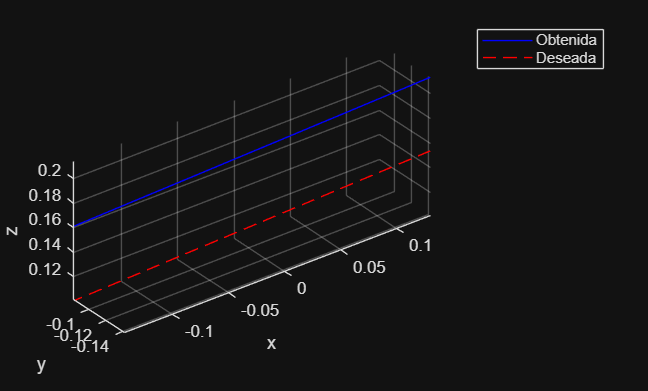


figure; plot3(P_hist(1,:), P_hist(2,:), P_hist(3,:), 'b', ...
              [Pi(1) Pf(1)], [Pi(2) Pf(2)], [Pi(3) Pf(3)], 'r--');
grid on; axis equal; legend('Obtenida','Deseada');
xlabel('x'); ylabel('y'); zlabel('z');



%% ------------- Cinemática directa y Jacobiano -------------
function [T, Px, Py, Pz, J] = cinematica(th1, th2, d3)
    d1 = 0.15;   d2 = 0.06;
    a1 = 0.13;   a2 = 0.13571 + 0.006;

    A1 = tqi(th1,        d1, 0,  a1);
    A2 = tqi(th2 - pi/2, d2, pi, a2);
    A3 = tqi(0,          d3, 0,  0);

    T1 = A1;  T2 = A1*A2;  T3 = T2*A3;
    T = T3;
    Px = T(1,4);  Py = T(2,4);  Pz = T(3,4);

    z0 = [0;0;1];     p0 = [0;0;0];
    z1 = T1(1:3,3);   p1 = T1(1:3,4);
    z2 = T2(1:3,3);
    pe = T3(1:3,4);

    J = [cross(z0, pe-p0), cross(z1, pe-p1), z2;
         z0,               z1,               [0;0;0]];
end

function Tq = tqi(tht, d, alp, a)
    ct = cos(tht);  st = sin(tht);
    ca = cos(alp);  sa = sin(alp);
    Tq = [ct, -st*ca,  st*sa, a*ct;
          st,  ct*ca, -ct*sa, a*st;
          0,   sa,     ca,    d;
          0,   0,      0,     1];
end

%% ------------- Cinemática inversa -------------
function [th1ar, th1ab, th2ar, th2ab, d3] = cinematica_inversa(Px, Py, Pz)
    a1 = 0.13;  a2 = 0.13571 + 0.006;
    d1 = 0.15;  d2 = 0.06;

    aph = atan2(Py, Px);
    d   = hypot(Px, Py);

    cosB   = max(-1, min(1, (d^2 + a1^2 - a2^2)/(2*d*a1)));
    cosphi = max(-1, min(1, (a1^2 + a2^2 - d^2)/(2*a1*a2)));
    B   = acos(cosB);
    phi = acos(cosphi);

    th1ar = aph + B;
    th1ab = aph - B;
    th2ar = phi - pi/2;
    th2ab = 3*pi/2 - phi;
    d3    = (d1) - Pz;

    wrap  = @(a) atan2(sin(a), cos(a));
    th1ar = wrap(th1ar);  th1ab = wrap(th1ab);
    th2ar = wrap(th2ar);  th2ab = wrap(th2ab);
end